# Box Lift - Fatigue EMG Plots

clear all;
clc;

%Set the Directory (ENTER INFO HERE)
cd('ENTER LOCATION HERE');

%Set the Participant ID
participant_ID = 'P6';

%Determine the MVIC for the participant
if convertCharsToStrings(participant_ID) == 'P7'
    Biceps_MVIC = 0.1831;
    Triceps_MVIC = 0.0382;
end

if convertCharsToStrings(participant_ID) == 'P6'
    Biceps_MVIC = 0.1313;
    Triceps_MVIC = 0.0528;
end

%Load the Data
load(strcat(participant_ID,"_NoExo.mat"));
load(strcat(participant_ID,"_Exo.mat"));

NoExo_Biceps = NoExo.FatigueLift.FoldedCycles.Bicep/Biceps_MVIC;
Exo_Biceps = Exo.FatigueLift.FoldedCycles.Bicep/Biceps_MVIC;

time(1:2000,1) = .001:0.001:2;

## Peaks

NoExo_Peak = max(NoExo_Biceps);
Exo_Peak = max(Exo_Biceps);

Percent_Difference_Peak = ((Exo_Peak - NoExo_Peak) / (NoExo_Peak)) * 100;

## Plot Data - Bicep Profile

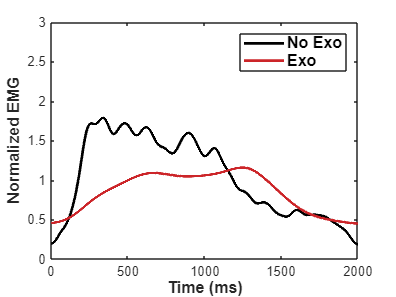

figure;
plot(NoExo_Biceps,'k','LineWidth',2);
hold on
plot(Exo_Biceps,'Color',[204 37 41]./255,'LineWidth',2);
xlabel('Time (ms)','FontWeight','bold', 'FontSize',12);
ylabel('Normalized EMG','FontWeight','bold', 'FontSize',12);
legend("No Exo", "Exo",'FontWeight','bold', 'FontSize',12);
ylim([0 3])
xticks(0:500:2000);

saveas(gcf,strcat('Profile_', participant_ID),'svg');